clc; clear all; close all;

PV = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_Sy.JPG')))./255;
PH = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_Sx.JPG')))./255;
PD = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_Diagonal.JPG')))./255;
PAD = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_AntiDiagonal.JPG')))./255;
PCD = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_SC_LR.JPG')))./255;
PCAD = double(rgb2gray(imread('C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Sagnac\Stokes_SC_RL.JPG')))./255;

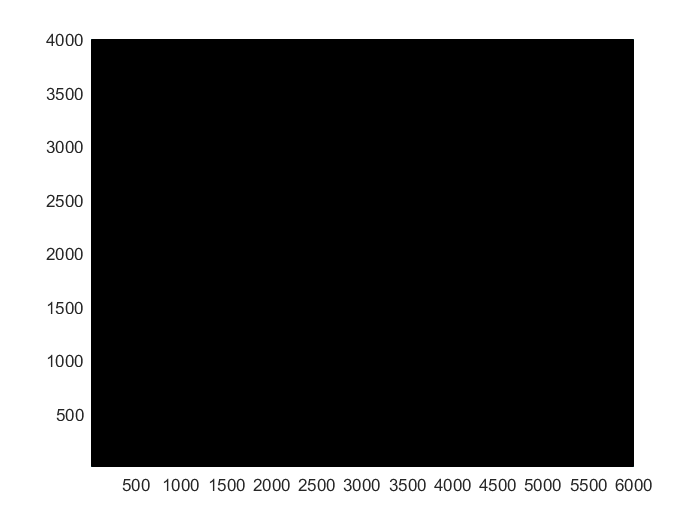

%Stokes
I = PH + PV;
Q = PH - PV;
U = PD - PAD;
V = PCD - PCAD;

pcolor(U)


L = sqrt(Q.^2 + U.^2);

A = sqrt(1/2*(I+abs(L)));
B = sqrt(1/2*(I-abs(L)));
TH = 1/2.*atan(U./Q);

for i = 1550:25:2300

    for j = 2000:25:2900
        if V(i,j)>0
            ellipse(A(i,j)*10,B(i,j)*10,TH(i,j),i,j,"r")
            hold on
        else
            ellipse(A(i,j)*10,B(i,j)*10,TH(i,j),i,j,"b")
            hold on
        end
    end
    
end

function h=ellipse(ra,rb,ang,x0,y0,C,Nb)
% Ellipse adds ellipses to the current plot
%
% ELLIPSE(ra,rb,ang,x0,y0) adds an ellipse with semimajor axis of ra,
% a semiminor axis of radius rb, and an orientation of the semimajor
% axis with an angle of ang (in radians) rotated counter-clockwise 
% from the x-axis.  The ellipse is centered at the point x0,y0.
%
% The length of ra, rb, and ang should be the same. 
% If ra is a vector of length L and x0,y0 scalars, L ellipses
% are added at point x0,y0.
% If ra is a scalar and x0,y0 vectors of length M, M ellipse are with the same 
% radii are added at the points x0,y0.
% If ra, x0, y0 are vectors of the same length L=M, M ellipses are added.
% If ra is a vector of length L and x0, y0 are  vectors of length
% M~=L, L*M ellipses are added, at each point x0,y0, L ellipses of radius ra.
%
% ELLIPSE(ra,rb,ang,x0,y0,C)
% adds ellipses of color C. C may be a string ('r','b',...) or the RGB value. 
% If no color is specified, it makes automatic use of the colors specified by 
% the axes ColorOrder property. For several ellipses C may be a vector.
%
% ELLIPSE(ra,rb,ang,x0,y0,C,Nb), Nb specifies the number of points
% used to draw the ellipse. The default value is 300. Nb may be specified
% for each ellipse individually, in which case it should be the same
% length as ra, rb, etc.
%
% h=ELLIPSE(...) returns the handles to the ellipses.
%
% usage exmple: the following produces a red ellipse centered at 1,1
% and tipped down at a 45 deg axis from the x axis
% ellipse(1,2,pi/4,1,1,'r')
%
% note that if ra=rb, ELLIPSE plots a circle
%

% written by D.G. Long, Brigham Young University, based on the
% CIRCLES.m original written by Peter Blattner, Institute of 
% Microtechnology, University of Neuchatel, Switzerland, blattner@imt.unine.ch

% Check the number of input arguments 

if nargin<1,
  ra=[];
end;
if nargin<2,
  rb=[];
end;
if nargin<3,
  ang=[];
end;

if nargin<5,
  x0=[];
  y0=[];
end;
 
if nargin<6,
  C=[];
end

if nargin<7,
  Nb=[];
end

% set up the default values

if isempty(ra),ra=1;end;
if isempty(rb),rb=1;end;
if isempty(ang),ang=0;end;
if isempty(x0),x0=0;end;
if isempty(y0),y0=0;end;
if isempty(Nb),Nb=300;end;
if isempty(C),C=get(gca,'colororder');end;

% work on the variable sizes

x0=x0(:);
y0=y0(:);
ra=ra(:);
rb=rb(:);
ang=ang(:);
Nb=Nb(:);

if isstr(C),C=C(:);end;

if length(ra)~=length(rb),
  error('length(ra)~=length(rb)');
end;
if length(x0)~=length(y0),
  error('length(x0)~=length(y0)');
end;

% how many inscribed elllipses are plotted

if length(ra)~=length(x0)
  maxk=length(ra)*length(x0);
else
  maxk=length(ra);
end;

% drawing loop

for k=1:maxk
  
  if length(x0)==1
    xpos=x0;
    ypos=y0;
    radm=ra(k);
    radn=rb(k);
    if length(ang)==1
      an=ang;
    else
      an=ang(k);
    end;
  elseif length(ra)==1
    xpos=x0(k);
    ypos=y0(k);
    radm=ra;
    radn=rb;
    an=ang;
  elseif length(x0)==length(ra)
    xpos=x0(k);
    ypos=y0(k);
    radm=ra(k);
    radn=rb(k);
    an=ang(k)
  else
    rada=ra(fix((k-1)/size(x0,1))+1);
    radb=rb(fix((k-1)/size(x0,1))+1);
    an=ang(fix((k-1)/size(x0,1))+1);
    xpos=x0(rem(k-1,size(x0,1))+1);
    ypos=y0(rem(k-1,size(y0,1))+1);
  end;

  % draw ellipse
  
  co=cos(an);
  si=sin(an);
  the=linspace(0,2*pi,Nb(rem(k-1,size(Nb,1))+1,:)+1);
  %  x=radm*cos(the)*co-si*radn*sin(the)+xpos;
  %  y=radm*cos(the)*si+co*radn*sin(the)+ypos;
  p=line(radm*cos(the)*co-si*radn*sin(the)+xpos,radm*cos(the)*si+co*radn*sin(the)+ypos);

  set(p,'color',C(rem(k-1,size(C,1))+1,:));
  
  % output handles to each ellipse if output variable specified
  
  if nargout > 0
    h(k)=p;
  end
  
end

end

